# Finding the optimal bin number, with events

load ev_nbins_agg_211012-130507_0.mat

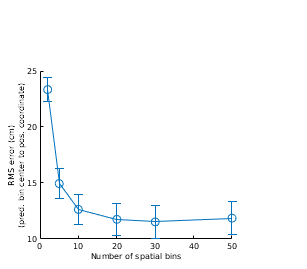

nbins = res(1).nbins;
rms_c_errs = cell2mat(arrayfun(@(x)mean(x.c_err,3), res, 'UniformOutput', false)).';

figure;
errorbar(nbins, mean(rms_c_errs), 1.96*sem(rms_c_errs), '-o');
xlabel 'Number of spatial bins'
ylabel(sprintf('RMS error (cm)\n(pred. bin center to pos. coordinate)'));
figure_format([2 1.75]);
Utils.printto('events_figs/f2_supplements', 'choosing_bin_size.pdf');